# **Matlab案例代码解析**

## 1. 基础函数使用案例

### 1.1  基础知识技巧

#### 1.1.2 考拉兹猜想（角谷猜想）

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

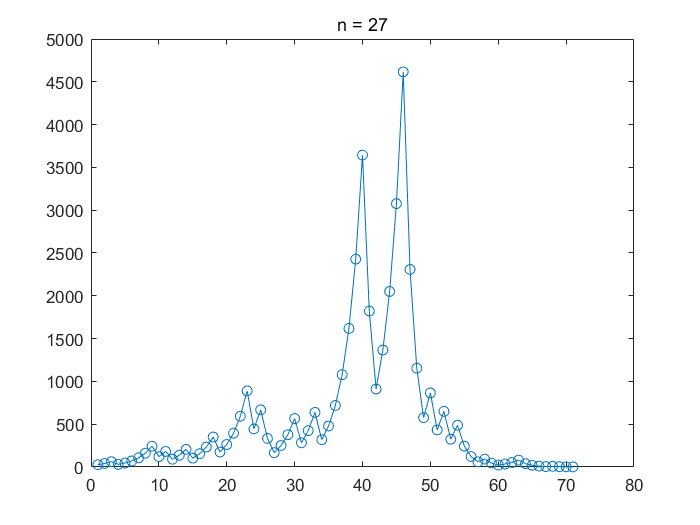

% 给定一个正整数 n
n = 27;
k = 1;
process = n;
% 让它一直循环下去，如果不收敛到 1，嘿嘿
while 1
    % 记录它的变化
    process(k) = n;
    % 整除 2 则除 2，否则 乘 3 加 1 再除 2，如此循环下去
    if mod(n, 2) == 0
        n = n / 2;
    else
        n = (3*n + 1) / 2;
    end
    k = k + 1;
    % 当然不能忘了要给循环退出条件
    if n == 1
        process(k) = n;
        break;
    end
end
% 绘图
plot(process, '-o');
title(sprintf('n = %d', process(1)));

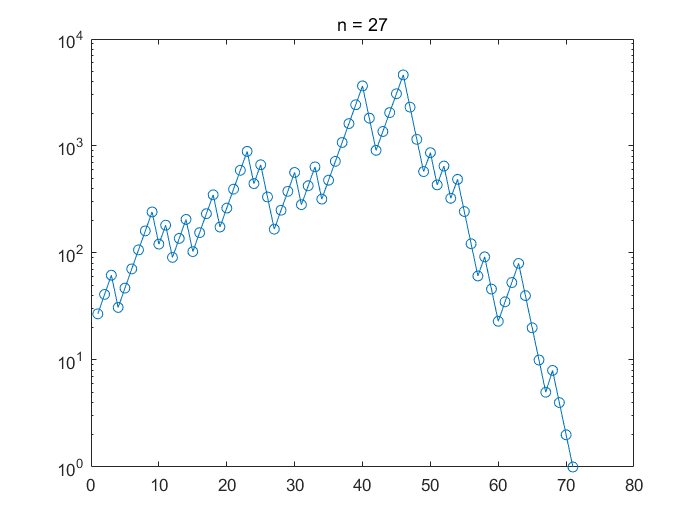

% 更直观点
semilogy(process, '-o');
title(sprintf('n = %d', process(1)));